# Import data from spreadsheet

Script for importing data from the following spreadsheet:

## Import data

clear all

opts = spreadsheetImportOptions("NumVariables", 5);

% Specify sheet and range
opts.Sheet = "Data";
opts.DataRange = "A2:E236";

% Specify column names and types
opts.VariableNames = ["Time", "GDPC1", "PCECTPI", "TB3MS", "GS10"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double"];

% Import the data
data = readtable("DatiProject.xlsx", opts, "UseExcel", false);

opts = spreadsheetImportOptions("NumVariables", 246);

% Specify sheet and range
opts.Sheet = "DataForFactors";
opts.DataRange = "A2:IL236";

% Specify column names and types
opts.VariableNames = ["Time", "PCECC96", "PCDGx", "PCESVx", "PCNDx", "GPDIC1", "FPIx", "Y033RC1Q027SBEAx", "PNFIx", "PRFIx", "A014RE1Q156NBEA", "GCEC1", "A823RL1Q225SBEA", "FGRECPTx", "SLCEx", "EXPGSC1", "IMPGSC1", "DPIC96", "OUTNFB", "OUTBS", "OUTMS", "INDPRO", "IPFINAL", "IPCONGD", "IPMAT", "IPDMAT", "IPNMAT", "IPDCONGD", "IPB51110SQ", "IPNCONGD", "IPBUSEQ", "IPB51220SQ", "TCU", "CUMFNS", "PAYEMS", "USPRIV", "MANEMP", "SRVPRD", "USGOOD", "DMANEMP", "NDMANEMP", "USCONS", "USEHS", "USFIRE", "USINFO", "USPBS", "USLAH", "USSERV", "USMINE", "USTPU", "USGOVT", "USTRADE", "USWTRADE", "CES9091000001", "CES9092000001", "CES9093000001", "CE16OV", "CIVPART", "UNRATE", "UNRATESTx", "UNRATELTx", "LNS14000012", "LNS14000025", "LNS14000026", "UEMPLT5", "UEMP5TO14", "UEMP15T26", "UEMP27OV", "LNS13023621", "LNS13023557", "LNS13023705", "LNS13023569", "LNS12032194", "HOABS", "HOAMS", "HOANBS", "AWHMAN", "AWHNONAG", "AWOTMAN", "HWIx", "HOUST", "HOUST5F", "PERMIT", "HOUSTMW", "HOUSTNE", "HOUSTS", "HOUSTW", "CMRMTSPLx", "RSAFSx", "AMDMNOx", "ACOGNOx", "AMDMUOx", "ANDENOx", "INVCQRMTSPL", "PCECTPI", "PCEPILFE", "GDPCTPI", "GPDICTPI", "IPDBS", "DGDSRG3Q086SBEA", "DDURRG3Q086SBEA", "DSERRG3Q086SBEA", "DNDGRG3Q086SBEA", "DHCERG3Q086SBEA", "DMOTRG3Q086SBEA", "DFDHRG3Q086SBEA", "DREQRG3Q086SBEA", "DODGRG3Q086SBEA", "DFXARG3Q086SBEA", "DCLORG3Q086SBEA", "DGOERG3Q086SBEA", "DONGRG3Q086SBEA", "DHUTRG3Q086SBEA", "DHLCRG3Q086SBEA", "DTRSRG3Q086SBEA", "DRCARG3Q086SBEA", "DFSARG3Q086SBEA", "DIFSRG3Q086SBEA", "DOTSRG3Q086SBEA", "CPIAUCSL", "CPILFESL", "WPSFD49207", "PPIACO", "WPSFD49502", "WPSFD4111", "PPIIDC", "WPSID61", "WPU0531", "WPU0561", "OILPRICEx", "AHETPIx", "CES2000000008x", "CES3000000008x", "COMPRMS", "COMPRNFB", "RCPHBS", "OPHMFG", "OPHNFB", "OPHPBS", "ULCBS", "ULCMFG", "ULCNFB", "UNLPNBS", "FEDFUNDS", "TB3MS", "TB6MS", "GS1", "GS10", "MORTGAGE30US", "AAA", "BAA", "BAA10YM", "MORTG10YRx", "TB6M3Mx", "GS1TB3Mx", "GS10TB3Mx", "CPF3MTB3Mx", "BOGMBASEREALx", "M1REAL", "M2REAL", "BUSLOANSx", "CONSUMERx", "NONREVSLx", "REALLNx", "REVOLSLx", "TOTALSLx", "DRIWCIL", "TABSHNOx", "TLBSHNOx", "LIABPIx", "TNWBSHNOx", "NWPIx", "TARESAx", "HNOREMQ027Sx", "TFAABSHNOx", "VIXCLSx", "USSTHPI", "SPCS10RSA", "SPCS20RSA", "TWEXAFEGSMTHx", "EXUSEU", "EXSZUSx", "EXJPUSx", "EXUSUKx", "EXCAUSx", "UMCSENTx", "USEPUINDXM", "B020RE1Q156NBEA", "B021RE1Q156NBEA", "GFDEGDQ188S", "GFDEBTNx", "IPMANSICS", "IPB51222S", "IPFUELS", "UEMPMEAN", "CES0600000007", "TOTRESNS", "NONBORRES", "GS5", "TB3SMFFM", "T5YFFM", "AAAFFM", "WPSID62", "PPICMM", "CPIAPPSL", "CPITRNSL", "CPIMEDSL", "CUSR0000SAC", "CUSR0000SAD", "CUSR0000SAS", "CPIULFSL", "CUSR0000SA0L2", "CUSR0000SA0L5", "CES0600000008", "DTCOLNVHFNM", "DTCTHFNM", "INVEST", "HWIURATIOx", "CLAIMSx", "BUSINVx", "ISRATIOx", "CONSPIx", "CP3M", "COMPAPFF", "PERMITNE", "PERMITMW", "PERMITS", "PERMITW", "NIKKEI225", "NASDAQCOM", "CUSR0000SEHC", "TLBSNNCBx", "TLBSNNCBBDIx", "TTAABSNNCBx", "TNWMVBSNNCBx", "TNWMVBSNNCBBDIx", "TLBSNNBx", "TLBSNNBBDIx", "TABSNNBx", "TNWBSNNBx", "TNWBSNNBBDIx", "CNCFx", "SP500", "SPIndust", "SPDivYield", "SPPERatio"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
% Import the data
fdata = readtable("DatiProject.xlsx", opts, "UseExcel", false);
clear opts

### Variables transformation

y = log(data.GDPC1);
dy = diff(y);
lpce = log(data.PCECTPI);
infl = diff(lpce);
tspread = data.GS10 - data.TB3MS ;
time = data.Time;
time = time + years(-1); % we noticed that the data was shifted +1 year wrt FRED's
                         % plot(data.Time, data.GDPC1) to check. GFC
                         % lowest should be 2009 Q2
time.Format = "MM-uuuu";

train = time <= "07-1985"; % July because it must end on the 1985 Q2

VAR matrix

dY = [dy, infl, tspread(2:end)]; 
Y = [y,[0;infl] ,tspread];
% dY appears to create problems in VAR model selection
% Using dYm in VAR model selection with vecm we get one kink
% for each lag, whereas with the dY above there is no king at lag = 2

### Plot

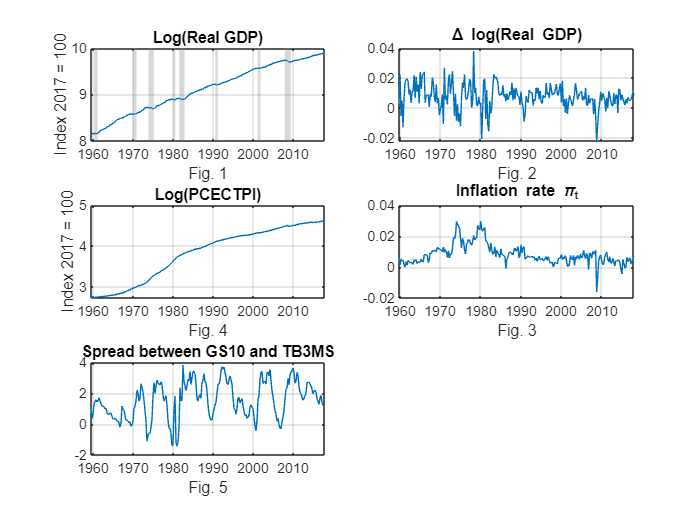

figure  
 
 
subplot(3,2,1)
plot(time,y)
grid on
title("Log(Real GDP)")
xlabel("Fig. 1")
ylabel("Index 2017 = 100")
recessionplot
 
 
subplot(3,2,2)
plot(time(2:end),dy)
grid on
title("\Delta log(Real GDP)")
xlabel("Fig. 2")
 
 
subplot(3,2,3)
plot(time, lpce)
title("Log(PCECTPI)")
xlabel("Fig. 4")
ylabel("Index 2017 = 100")
grid on
 
 
subplot(3,2,4)
plot(time(2:end),infl)
title("Inflation rate \pi_t")
xlabel("Fig. 3")
grid on
 
 
subplot(3,2,5)
plot(time,tspread)
title("Spread between GS10 and TB3MS")
xlabel("Fig. 5")
grid on

- Fig1 Trend (supported by ACF), no season, cycles

- Fig2 Approx. mean reverting. Example of volatility clustering (periods with higher variance). no trend, no seasonality

- Fig3 cycles. Apparently trend changing slope in 1980, no seasonality ( acf shows suspicious higher spikes)

- Fig4 same as figure 1

- Fig5 trend with cycles. Doesn't look like it is seasonal

### Study of autocorrelation and partial autocorrelation

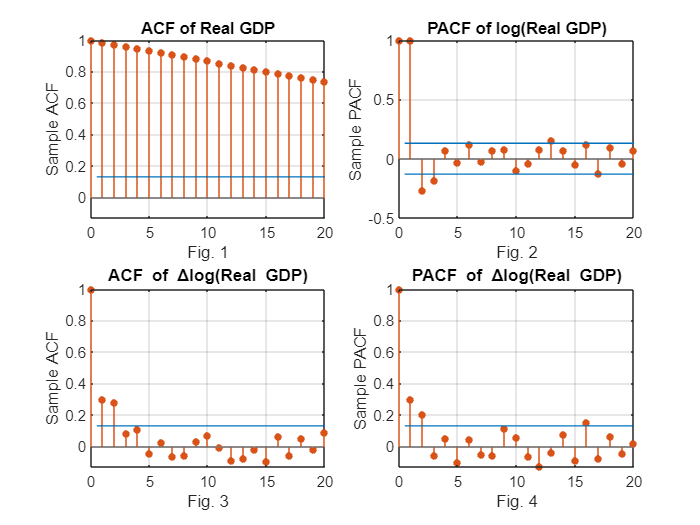

figure  
 
 
subplot(2,2,1)
autocorr(y)
title("ACF of Real GDP")
xlabel("Fig. 1")
ylabel("Sample ACF")
 
 
subplot(2,2,2)
parcorr(y)
title("PACF of log(Real GDP)")
xlabel("Fig. 2")
ylabel("Sample PACF")
 
 
subplot(2,2,3)
autocorr(dy)
title("ACF of \Deltalog(Real GDP)")
xlabel("Fig. 3")
ylabel("Sample ACF")
 
 
subplot(2,2,4)
parcorr(dy)
title("PACF of \Deltalog(Real GDP)")
xlabel("Fig. 4")
ylabel("Sample PACF");

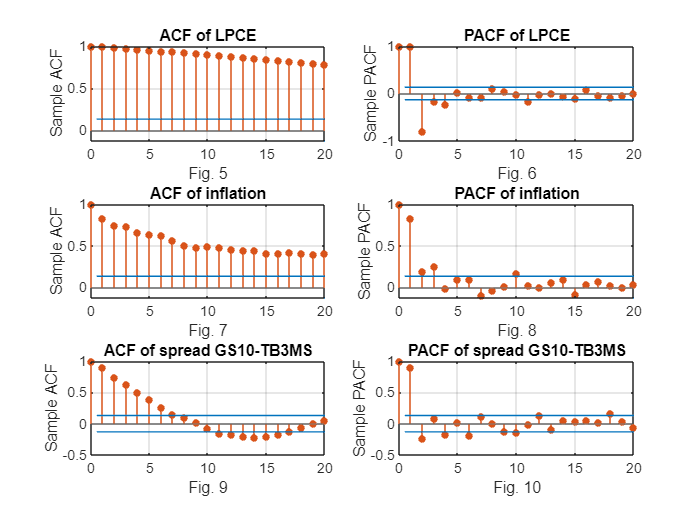

 
 
figure
subplot(3,2,1)
autocorr(lpce)
title("ACF of LPCE")
xlabel("Fig. 5")
ylabel("Sample ACF")
 
 
subplot(3,2,2)
parcorr(lpce)
title("PACF of LPCE")
xlabel("Fig. 6")
ylabel("Sample PACF")
 
 
subplot(3,2,3)
autocorr(infl)
title("ACF of inflation")
xlabel("Fig. 7")
ylabel("Sample ACF")
 
 
subplot(3,2,4)
parcorr(infl)
title("PACF of inflation")
xlabel("Fig. 8")
ylabel("Sample PACF")
 
 
subplot(3,2,5)
autocorr(tspread)
title("ACF of spread GS10-TB3MS")
xlabel("Fig. 9")
ylabel("Sample ACF")
 
 
subplot(3,2,6)
parcorr(tspread)
title("PACF of spread GS10-TB3MS")
xlabel("Fig. 10")
ylabel("Sample PACF")

### Extract 1st Principal Component from fdata

% Get first principal component
fnorm = normalize(fdata(train,2:end)); %we could use zscore as well
fnorm = table2array(fnorm);
[coeff,score,latent,tsquared,explained,mu] = pca(fnorm);

Fhat = coeff(:,1); 
% rows = coefficients for the 245 factors
% cols correspond to the 234 principal components. 

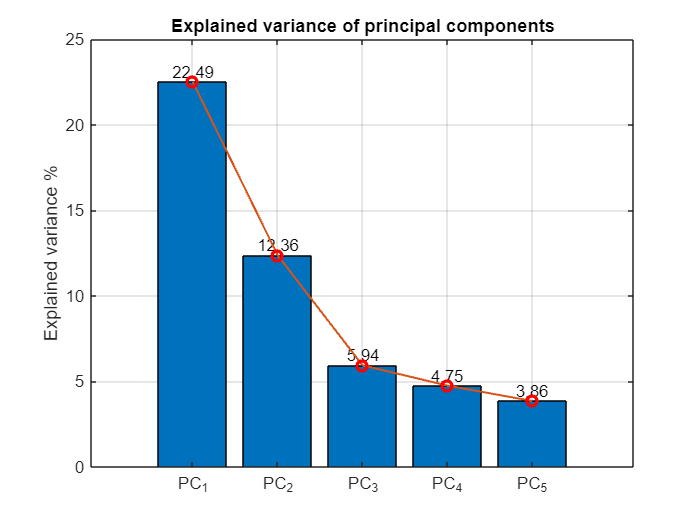


figure
xticks = {"PC_1","PC_2","PC_3","PC_4","PC_5"};
bar(1:5,explained(1:5)) % screeplot da abbellire
labels = arrayfun(@(values) num2str(values, '%2.2f'), explained(1:5), 'UniformOutput',false);
text(1:5, explained(1:5), labels,'HorizontalAlignment','center','VerticalAlignment','bottom')
grid on
title("Explained variance of principal components")
xticklabels(xticks)
ylabel("Explained variance %")
ylim([0,25])
hold on 
plot(1:5, explained(1:5), 'LineWidth',1.2)
hold on 
plot(1:5, explained(1:5),'o', 'LineWidth',2, 'Color','red')

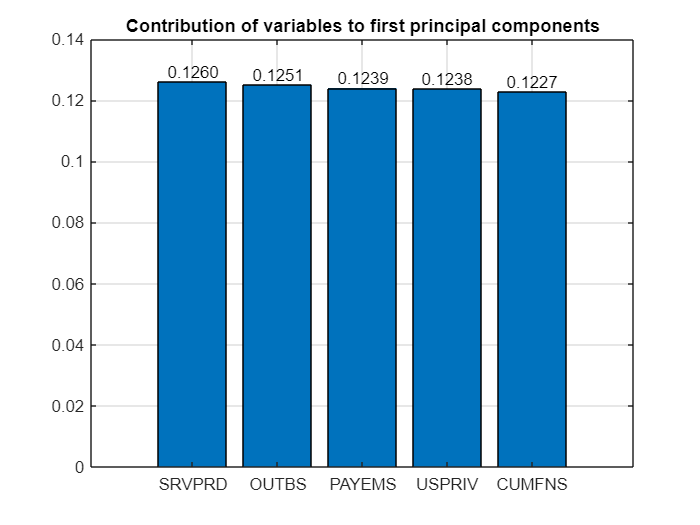

[maxima,positions]=sort(Fhat, "descend");
out_x=maxima(1:5);         % 5 first values
out_pos=positions(1:5);

figure
xticks = {fdata.Properties.VariableNames(out_pos)};
bar(1:5,out_x)
labels = arrayfun(@(values) num2str(values, '%2.4f'), out_x, 'UniformOutput',false);
text(1:5, out_x, labels,'HorizontalAlignment','center','VerticalAlignment','bottom')
title("Contribution of variables to first principal components")
xticklabels(xticks{1,:})
grid on

We test for stationarity

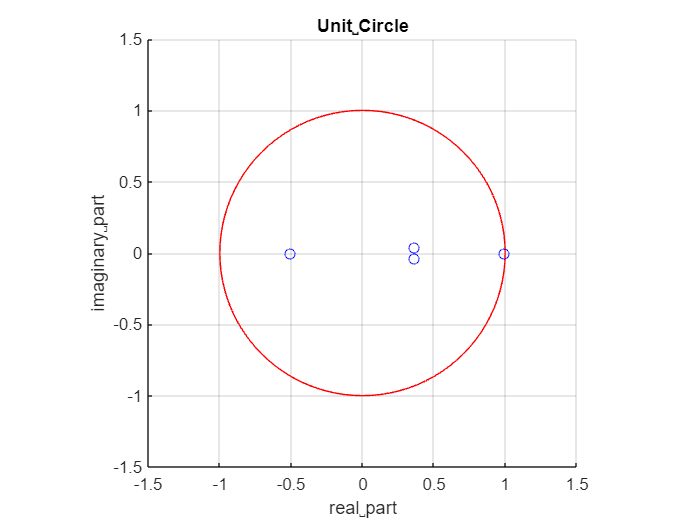

ir =   -0.5050 + 0.0000i
   0.3667 - 0.0397i
   0.3667 + 0.0397i
   0.9967 + 0.0000i


mhat = estimate(arima(4,0,0),y, 'Display','off');
ir = ARroots(cell2mat(mhat.AR))

max(abs(ir))

ans = 0.9967

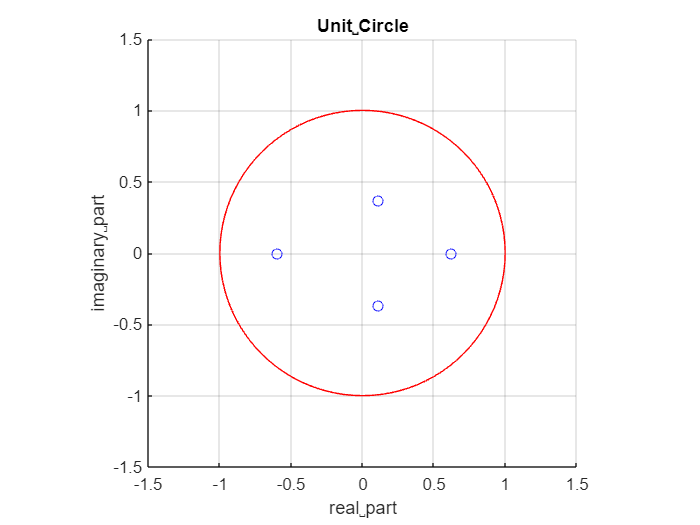

ir =    0.1134 - 0.3688i
   0.1134 + 0.3688i
  -0.5973 + 0.0000i
   0.6211 + 0.0000i


%%%%%%
% mhat = estimate(arima(4,1,0),y, 'Display','off');
% ir = ARroots(cell2mat(mhat.AR))
% max(abs(ir))
%%%%%%% letting arima take the first difference or doing it ourself leads
%%%%%%% to the same result
mhat = estimate(arima(4,0,0),dy, 'Display','off');
ir = ARroots(cell2mat(mhat.AR))

max(abs(ir))

ans = 0.6211

### ADF test for stationarity

We consider different specifications of the DF test. When Model=ARD, the alternative is an AR model with constant, when Model=TS the alternative is that y is stationary around a linear trend.

% ADF for stationarity
[h,pval,stat,critval] = adftest(y,'Model','AR','Lag',0) % stat < critical so we reject the null hp of unit root

h = logical
   0


pval = 0.9990

stat = 13.6974

critval = -1.9421

 % E' possibile dover usare TS come alternativa visto il palese trend lineare nella serie?
 % Teoria: ARD suppone una serie SENZA TREND, per testare la stazionarita':
 % se abbiamo una serie con un palese trend, puo' essere sbagliato usare
 % ARD?

 %check 'help adftest' to choose between AR and ARD


[h,pval,stat,critval] = adftest(y,'Model','TS','Lag',0)

h = logical
   0


pval = 0.8868

stat = -1.2921

critval = -3.4314

[h,pval,stat,critval] = adftest(y,'Model','AR','Lag',1)

h = logical
   0


pval = 0.9990

stat = 7.3409

critval = -1.9421

[h,pval,stat,critval] = adftest(y,'Model','TS','Lag',1)

h = logical
   0


pval = 0.6887

stat = -1.8021

critval = -3.4315

[h,pval,stat,critval] = adftest(diff(y),'Model','ARD','Lag',1)

h = logical
   1


pval = 1.0000e-03

stat = -7.2971

critval = -2.8743

While the last test makes sense, why does the first one reject the null hypothesis as well?

### VAR Model Selection

Starting from a VAR model with $\Delta y,\pi_t$ and ${\textrm{Tspread}}_t$ select a lag order "p" with Akaike Information Criterion

## Lag selection in VAR

for loop to assess best lag through AIC

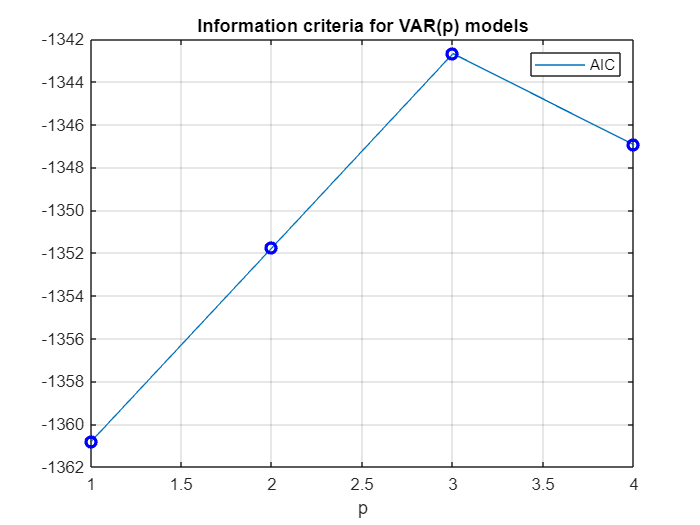

pmax = 4;
aic = NaN(pmax,1); % initialize AIC table, 4 max lags and just 1 model (the VAR)
train = time <= "07-1985"; % July because it must end on the 1985 Q2
T0 = length(y(train));

for ii = 1:pmax
    mhat1 = estimate(varm(3,ii),dY(1:T0,:),'Display','off'); % I use the first 101 observation, which end on 1985 Q2   
    summhat = summarize(mhat1); 
    aic(ii,1) = summhat.AIC;
end

figure

plot(1:4,aic(:,1));
hold on
plot(1:4, aic(1:4),'o', 'LineWidth',2, 'Color','blue')
grid on
legend('AIC'); xlabel('p'); title('Information criteria for VAR(p) models')

Get the residuals from VAR(1) 

Plot ACF and PACF of residuals

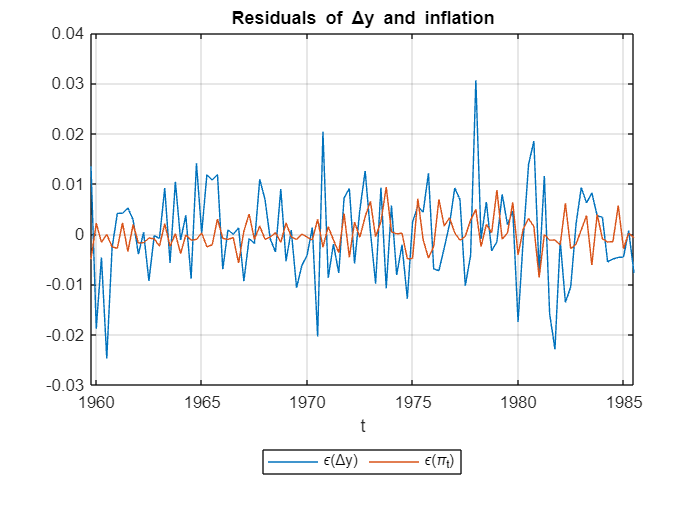

mhat = estimate(varm(3,1),dY(1:T0,:),'Display','off'); % I use the first 101 observation, which end on 1985 Q2   
res_var = infer(mhat,dY(1:T0,:));
res_dy = res_var(:,1);
res_inf = res_var(:,2);
res_tspread = res_var(:,3);

figure
plot(time(2:T0),res_dy)
hold on
plot(time(2:T0),res_inf)
grid on
xlabel("t")
title("Residuals of \Deltay and inflation")
legend("\epsilon(\Deltay)", "\epsilon(\pi_{t})", "Location","southoutside", "Orientation","horizontal")
hold off

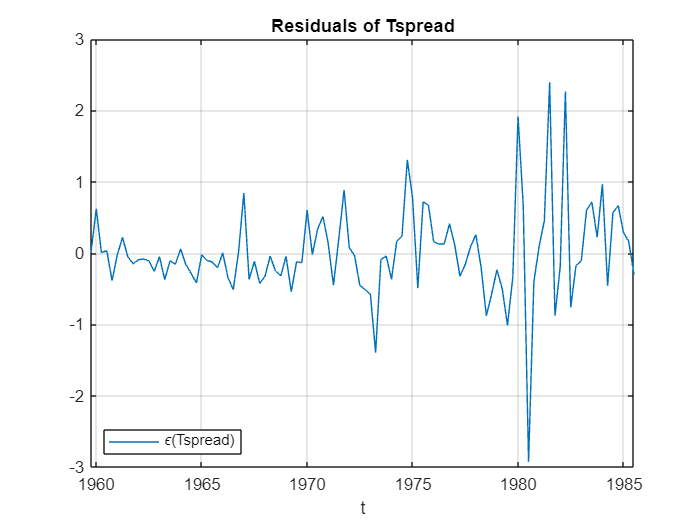


figure
plot(time(2:T0),res_tspread)
grid on
xlabel("t")
title("Residuals of Tspread")
legend("\epsilon(Tspread)", "Location","southwest", "Orientation","horizontal")

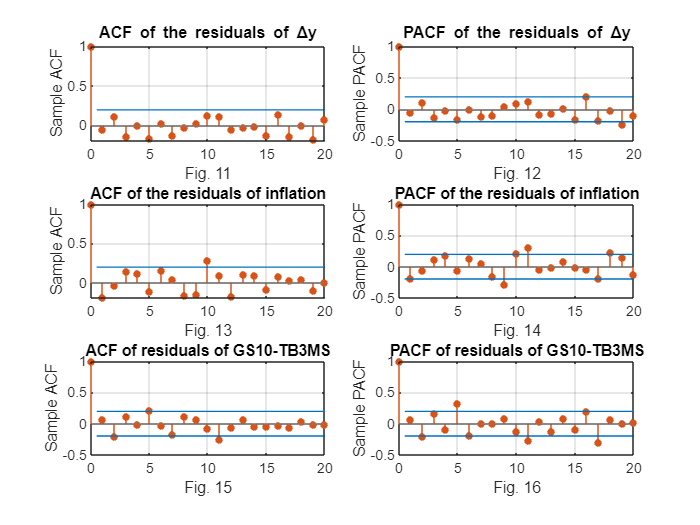

figure
subplot(3,2,1)
autocorr(res_dy)
title("ACF of the residuals of \Deltay")
xlabel("Fig. 11")
ylabel("Sample ACF")
 
 
subplot(3,2,2)
parcorr(res_dy)
title("PACF of the residuals of \Deltay")
xlabel("Fig. 12")
ylabel("Sample PACF")
 
 
subplot(3,2,3)
autocorr(res_inf)
title("ACF of the residuals of inflation")
xlabel("Fig. 13")
ylabel("Sample ACF")
 
 
subplot(3,2,4)
parcorr(res_inf)
title("PACF of the residuals of inflation")
xlabel("Fig. 14")
ylabel("Sample PACF")
 
 
subplot(3,2,5)
autocorr(res_tspread)
title("ACF of residuals of GS10-TB3MS")
xlabel("Fig. 15")
ylabel("Sample ACF")
 
 
subplot(3,2,6)
parcorr(res_tspread)
title("PACF of residuals of GS10-TB3MS")
xlabel("Fig. 16")
ylabel("Sample PACF")

## Model specification

mrw = arima('D',0,'Constant',0); 

mar4 = arima(4,0,0); %AR(4)

mvar4 = varm(3,4); % VAR(4)

mvar(p) = varm(3, p) % VAR(p)

marx =  vecm(1,0,4); % AR(4)-X 

% Define training set up to 1985 Q2
train = time <= "07-1985";
h = 1;
T = length(y);
T0 = length(y(train));                 
nmod = 5; 
fore = NaN(T,nmod +2); %2 extra columns to store the forecasts for the variable in level 
jj = T0;
ww = 100; % rolling widows length
wwx = 99;

while jj < T
     % disp([T-jj])
     %x1 = [0; Fhat(jj-ww:jj-1)]; % x(t-1) the zero adds the observation we're missing due to taking jj-1
     x1 = Fhat(jj-wwx:jj-1);
 
     % RW
     fore(jj+1,1) = y(jj);

     % AR(4) for Delta y
     fore(jj+1,2) = forecast(estimate(arima(4,1,0),y(jj-ww:jj),'Display','off'),h,y(jj-ww:jj)); % are we sure about arima(4,1,0) if we pass dy
     
     % VAR(4) for Delta y
     mvar4 = estimate(varm(3,4),dY(jj-ww:jj,:), "Display","off"); % VAR(4)
     tmpf = forecast(mvar4,h,dY(jj-ww:jj,:)); % var forecast
     fore(jj+1,3) = tmpf(:,1)';
     
     % VAR(1) for delta y % PROVARE CON DUE VISTA LA ACF
     mvar1= estimate(varm(3,1),dY(jj-ww:jj,:), "Display","off"); % VAR(4)
     tmpf = forecast(mvar1,h,dY(jj-ww:jj,:)); % var forecast
     fore(jj+1,4) = tmpf(:,1)';
     
     %VAR(2) with VECM
     % mvar2 = estimate(vecm(3,0,2),Y(jj-ww:jj,:), "Display","off"); % VAR(4)
     % tmpf = forecast(mvar2,h,Y(jj-ww:jj,:)); % var forecast
     % fore(jj+1,5) = tmpf(:,1)';
     
     % AR(4)-X for Delta p with spread
     tmp = estimate(vecm(1,0,4),y(jj-wwx:jj),"X",x1); %y instead of dy because vecm takes the difference
     fore(jj+1,5) = forecast(tmp,1,y(jj-wwx:jj),"X",Fhat(jj));

     jj=jj+1;
end

% go back to variable in level

for i = T0:length(y)-1
    fore(i+1,6) = y(i) + fore(i+1,3); % VAR(4)
    fore(i+1,7) = y(i) + fore(i+1,4); % VAR(1)
end

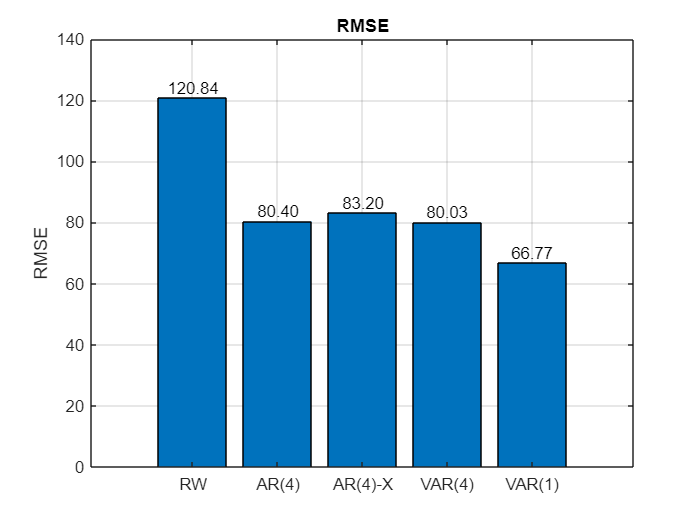

figure
mnames={'RW','AR(4)','AR(4)-X','VAR(4)','VAR(1)'};
F = exp(fore(T0+1:end,:));
A = exp(y(T0+1:end));
rmse = sqrt(mean((A-F).^2));
cols = [1:2,5:7];
bar(1:5,rmse(cols)); xticklabels(mnames); ylabel('RMSE')
labels = arrayfun(@(values) num2str(values, '%2.2f'), rmse(:,cols), 'UniformOutput',false);
text(1:5, rmse(cols), labels,'HorizontalAlignment','center','VerticalAlignment','bottom')
title("RMSE")
grid on


% %better performance 
1- rmse(cols)./rmse(1)

ans =          0    0.3346    0.3115    0.3377    0.4474


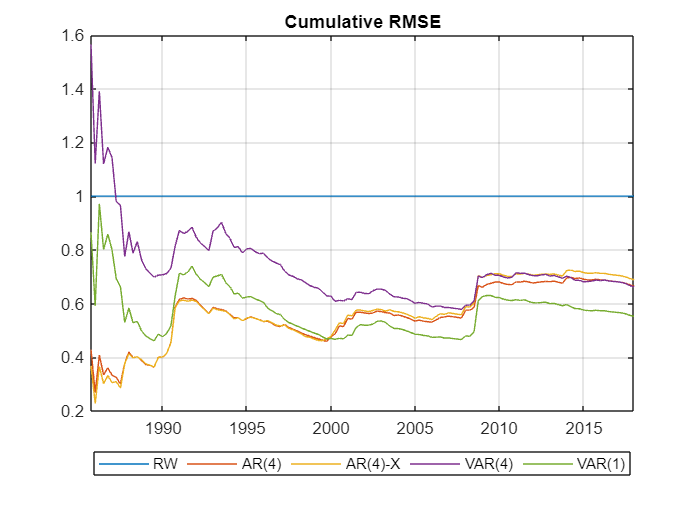

uhat2 = sqrt((1./(1:size(F(:,cols),1))').*cumsum((A-F(:,cols)).^2,1));

figure
plot(time(T0+1:end),uhat2./uhat2(:,1)); legend(mnames,'Location','southoutside','Orientation','horizontal')
grid on
title("Cumulative RMSE")

## Plots of all the forecasts

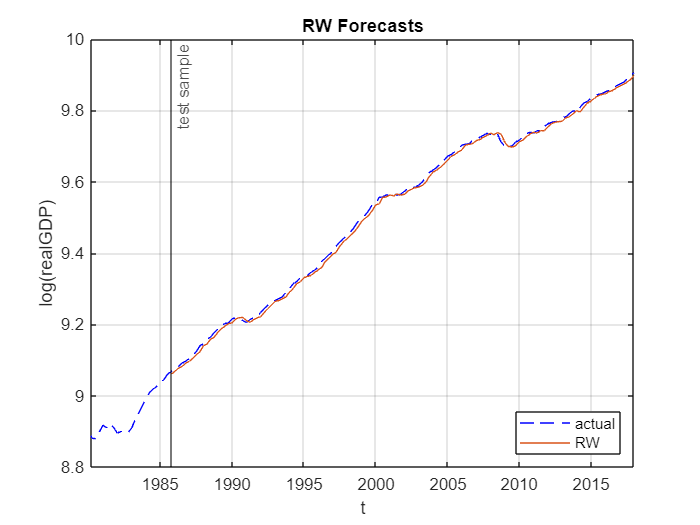

time_test = time(train==0);
figure
plot(time,y, '--', 'Color', 'blue', 'LineWidth', 0.5)
hold on
plot(time,fore(:,1))

xline(time_test(1), '-k','test sample');
xlim(["03-1980", time(end)])
xlabel("t")
ylabel("log(realGDP)")
title('RW Forecasts')

grid on
legend('actual','RW','Location','southeast')

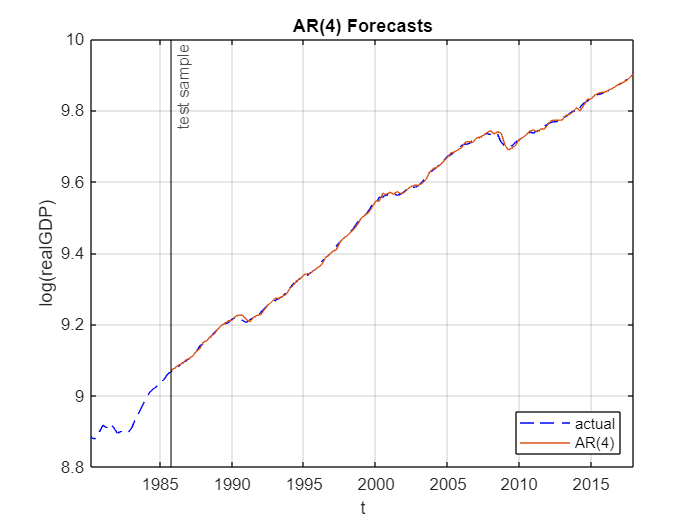

time_test = time(train==0);
figure
plot(time,y, '--', 'Color', 'blue', 'LineWidth', 0.5)
hold on
plot(time,fore(:,2))

xline(time_test(1), '-k','test sample');
xlim(["03-1980", time(end)])
xlabel("t")
ylabel("log(realGDP)")
title('AR(4) Forecasts')

grid on
legend('actual','AR(4)','Location','southeast')

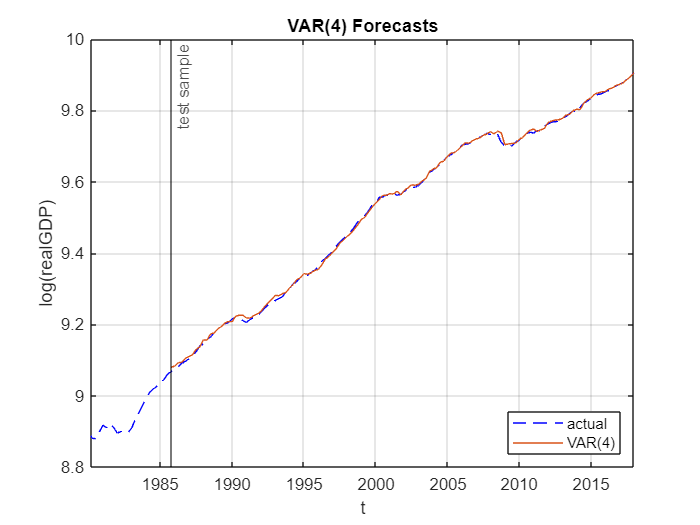


time_test = time(train==0);
figure
plot(time,y, '--', 'Color', 'blue', 'LineWidth', 0.5)
hold on
plot(time,fore(:,6))

xline(time_test(1), '-k','test sample');
xlim(["03-1980", time(end)])
xlabel("t")
ylabel("log(realGDP)")
title('VAR(4) Forecasts')

grid on
legend('actual','VAR(4)','Location','southeast')

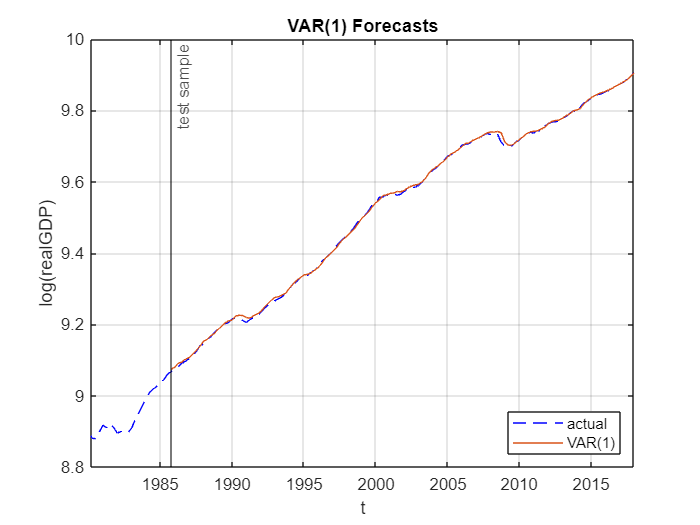

time_test = time(train==0);
figure
plot(time,y, '--', 'Color', 'blue', 'LineWidth', 0.5)
hold on
plot(time,fore(:,7))

xline(time_test(1), '-k','test sample');
xlim(["03-1980", time(end)])
xlabel("t")
ylabel("log(realGDP)")
title('VAR(1) Forecasts')

grid on
legend('actual','VAR(1)','Location','southeast')

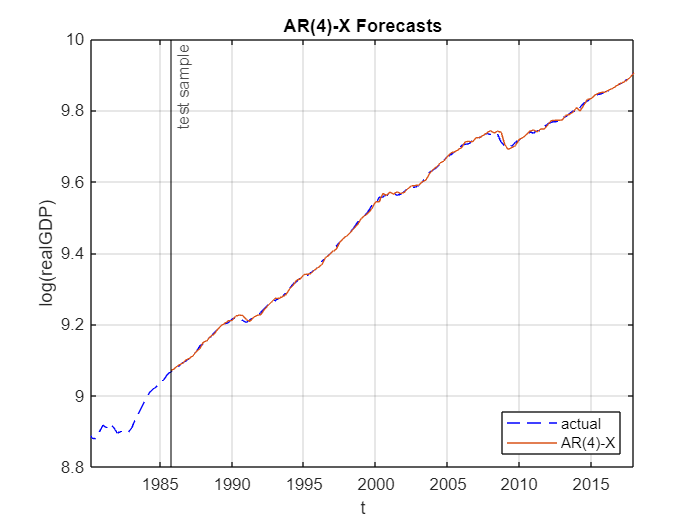

time_test = time(train==0);
figure
plot(time,y, '--', 'Color', 'blue', 'LineWidth', 0.5)
hold on
plot(time,fore(:,5))

xline(time_test(1), '-k','test sample');
xlim(["03-1980", time(end)])
xlabel("t")
ylabel("log(realGDP)")
title('AR(4)-X Forecasts')

grid on
legend('actual','AR(4)-X','Location','southeast')

## Bonus models

- Naive: Mean of all forecasts

- vecm(3,0,1)

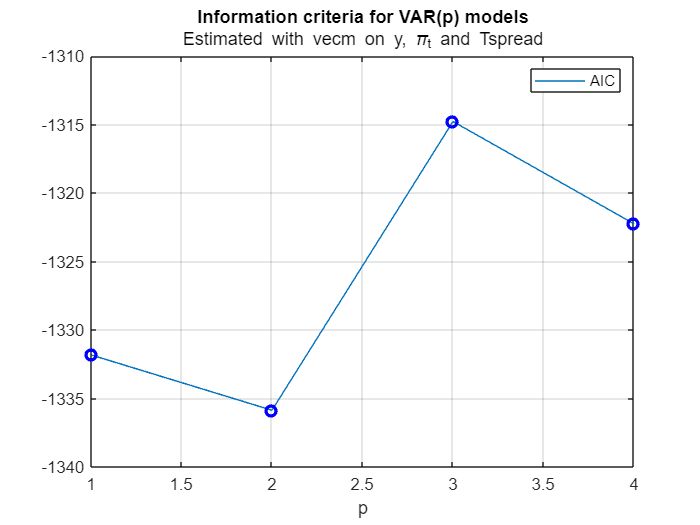

pmax = 4;
aic = NaN(pmax,1); % initialize AIC table, 4 max lags and just 1 model (the VECM)
train = time <= "07-1985"; % July because it must end on the 1985 Q2
T0 = length(y(train));

%rationale: we saw slight trends in the plots, we could take first differences
for ii = 1:pmax
    mhat1 = estimate(vecm(3,0,ii),Y(1:T0,:),'Display','off'); % I use the first 101 observation, which end on 1985 Q2   
    summhat = summarize(mhat1); 
    aic(ii,1) = summhat.AIC;
end
[val,p_opt]=min(aic(:,1));

figure
plot(1:4,aic(:,1))
hold on
plot(1:4, aic(1:4),'o', 'LineWidth',2, 'Color','blue')
grid on
legend('AIC'); xlabel('p'); title(['Information criteria for VAR(p) models'],['Estimated with vecm on y, \pi_t and Tspread'])


h = 1;
T = length(y);

nmod = 2; 
bonus = NaN(T,nmod+1);
jj = T0;
ww = 100; % rolling widows length 

cols = [1:2,5:7];
% Mixture of VECM with differences and factors
while jj < T

     tmp = estimate(vecm(3,0,p_opt),dY(jj-ww:jj,:)); %y recall vecm takes the difference
     tmpf = forecast(tmp,h,dY(jj-ww:jj,:));
     bonus(jj+1,1) = tmpf(:,1);

     bonus(jj+1,2) = mean(fore(jj+1,cols));


     jj = jj + 1;
end

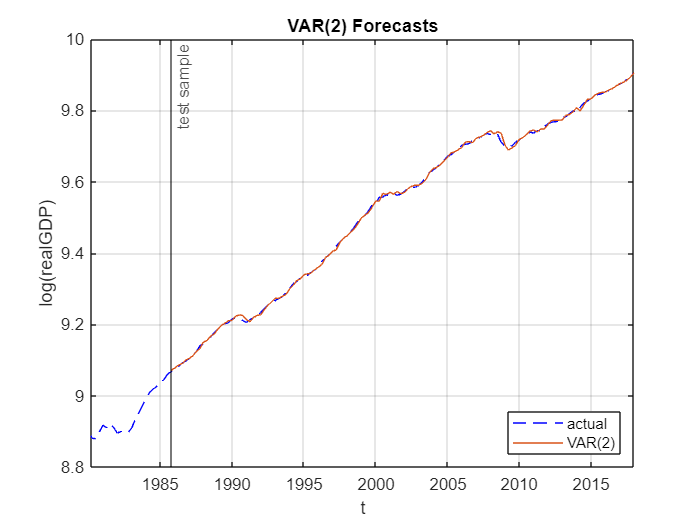

%go back to levels
for i = T0:length(y)-1
    bonus(i+1,3) = y(i) + bonus(i+1,1); %practical downside: difficult to interpret differencing y two times, but it works
end

figure
plot(time,y, '--', 'Color', 'blue', 'LineWidth', 0.5)
hold on
plot(time,fore(:,2))

xline(time_test(1), '-k','test sample');
xlim(["03-1980", time(end)])
xlabel("t")
ylabel("log(realGDP)")
title('VAR(2) Forecasts')

grid on
legend('actual','VAR(2)','Location','southeast')

Fb = exp(bonus(T0+1:end,2:3));
A = exp(y(T0+1:end));
rmseb = sqrt(mean((A-Fb).^2))

rmseb =    72.5628   56.7633


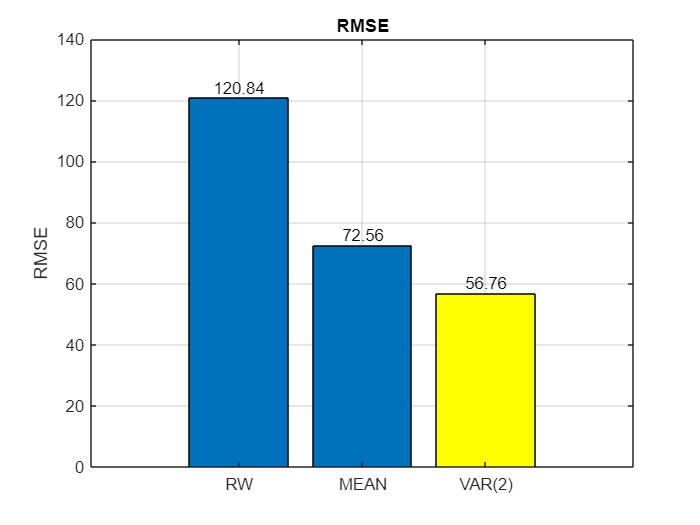


mnames={'RW','MEAN','VAR(2)'};
figure
h = bar(1:3,[rmse(1),rmseb], 'FaceColor','flat');
xticklabels(mnames); ylabel('RMSE')
labels = arrayfun(@(values) num2str(values, '%2.2f'), [rmse(1) rmseb], 'UniformOutput',false);
text(1:3, [rmse(1) rmseb], labels,'HorizontalAlignment','center','VerticalAlignment','bottom')
title("RMSE")
h.CData(3,:) = [1 1 0];
grid on

% %better performance
1- (rmseb./rmse(1))

ans =     0.3995    0.5302


## Functions

function inverted_roots = ARroots(arcoef)
    arcoef = arcoef(:);
    z = [-flipud(arcoef)' 1];
    inverted_roots = 1./roots(z);
    figure;
    center = [0, 0]; % Define the center of the circle
    radius = 1; % Define the radius of the circle
    rectangle('Position', [center - radius , 2 * radius , 2 * radius], 'Curvature', [1,1],'EdgeColor' ,[1,0,0]); % unit circle
    hold on
    y = imag(inverted_roots);
    x = real(inverted_roots);
    plot(x,y,'ob');
    axis equal; % Set aspect ratio to be equal so the circle looks like a circle
    % Set axis limits to ensure the entire circle is visible
    axis([-1.5 1.5 -1.5 1.5]);
    % Label the axes
    xlabel('real␣part');
    ylabel('imaginary␣part');
    %Title for the plot
    title('Unit␣Circle');
    % Grid
    grid on;
end